% ============================================
% Read CSV
% ============================================
data = readtable("../../lua/resultado/resultados.csv");   % <-- change to your filename

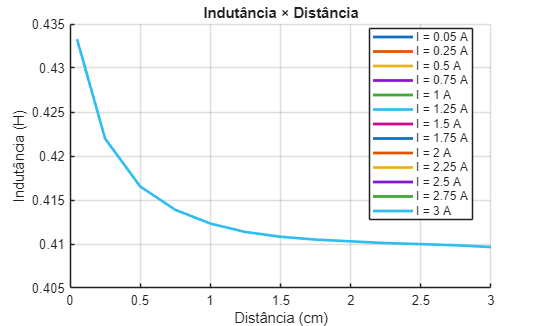



I   = data.Corrente_A_;          % or the exact column name
d   = -data.Distancia_cm_;       % multiply distance by -1
Fy  = data.ForcaFy_N_;
L   = data.Indutancia_H_;

% ============================================
% Get unique current values
% ============================================
unique_I = unique(I);

% ============================================
% Plot 1: Inductance × Distance
% ============================================
figure;
hold on;
grid on;

for k = 1:length(unique_I)
    Ik = unique_I(k);

    % select rows of this current
    mask = (I == Ik);
    
    % sorted by distance
    [d_sorted, idx] = sort(d(mask));
    L_sorted = L(mask);
    L_sorted = L_sorted(idx);

    plot(d_sorted, L_sorted, 'LineWidth', 2);
end

xlabel('Distância (cm)');
ylabel('Indutância (H)');
title('Indutância × Distância');
legend("I = " + string(unique_I) + " A", 'Location','best');
hold off;

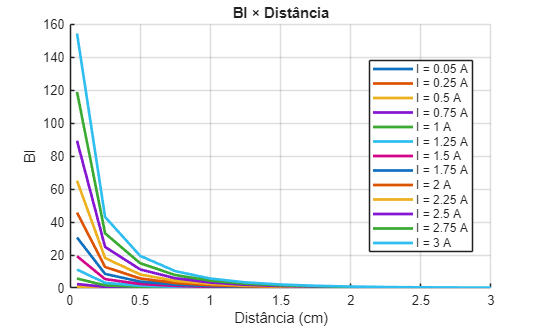


% ============================================
% Plot 2: (Force * Current) × Distance
% ============================================
figure;
hold on;
grid on;

for k = 1:length(unique_I)
    Ik = unique_I(k);

    mask = (I == Ik);

    % sorted by distance
    [d_sorted, idx] = sort(d(mask));
    Fy_sorted = Fy(mask);
    Fy_sorted = Fy_sorted(idx);

    plot(d_sorted, Fy_sorted * Ik, 'LineWidth', 2);
end

xlabel('Distância (cm)');
ylabel('Bl');
title('Bl × Distância');
legend("I = " + string(unique_I) + " A", 'Location','best');
hold off;

COMPARAÇÃO COM O MODELO ARITMÉTICO

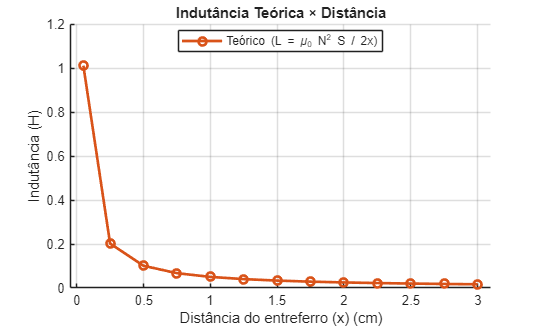

%% Inductance Calculation and Plotting Script (Corrected for Positive Distance)

% --- 1. Define Constants ---
u0 = 4 * pi * 1e-7;   % Permeability of free space (H/m)
N  = 2000;             % Number of turns
r_core_cm = 0.8;      % Core radius (cm)
r_core_m = r_core_cm / 100; % Core radius (m)

% Effective Area (S) calculated from the core radius
S = pi * r_core_m^2;  % Area (m^2)

% --- 2. Theoretical Inductance Calculation ---

% Distances provided (d_cm_theory is now the positive physical gap 'x' in cm)
d_cm_theory = [0.05, 0.25, 0.5, 0.75, 1, 1.25, 1.5, 1.75, 2.0, 2.25, 2.5, 2.75, 3.0]; 

% Convert distance (x) to meters for the formula
x_m_theory = d_cm_theory / 100; 

% Calculate theoretical inductance L_theory
% L = (u0 * N^2 * S) / (2 * x)
L_theory = (u0 * N^2 * S) ./ (2 * x_m_theory); 

%% --- 3. Plotting Theoretical Inductance ---
figure;
hold on;
grid on;

% Plot the theoretical curve (using d_cm_theory for the x-axis)
% Note: The x-axis now represents the positive air gap 'x'
plot(d_cm_theory, L_theory, 'o-', 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980]); 

% --- Labels and Title for the plot ---
xlabel('Distância do entreferro (x) (cm)');
ylabel('Indutância (H)');
title('Indutância Teórica × Distância');
legend('Teórico (L = \mu_0 N^2 S / 2x)', 'Location', 'best');

% Adjust axis limits for better viewing
min_d = min(d_cm_theory) - 0.1;
max_d = max(d_cm_theory) + 0.1;
xlim([min_d max_d]);
hold off;

BL CALCULADO

%% Magnetic Force Calculation Script

% --- 2. Define Inputs (Distances and Currents) ---
% Distances (x) in cm
x_cm = [0.05, 0.25, 0.5, 0.75, 1, 1.25, 1.5, 1.75, 2.0, 2.25, 2.5, 2.75, 3.0]; 
x_m = x_cm / 100; % Distance (x) in meters

% Currents (I) in Amperes
I_A = [0.05, 0.25, 0.5, 0.75, 1, 1.25, 1.5, 1.75, 2.0, 2.25, 2.5, 2.75, 3.0]; 

% --- 3. Calculate BL_formula ---
% BL = (u0 * N^2 * S) / (4 * x^2)
Const_part = (u0 * N^2 * S) / 4

Const_part = 2.5266e-04


Bl_values = Const_part ./ (x_m.^2) 

Bl_values = 1.0e+03 *

    1.0106    0.0404    0.0101    0.0045    0.0025    0.0016    0.0011    0.0008    0.0006    0.0005    0.0004    0.0003    0.0003



% The BL matrix is the same for all currents
Bl_matrix = Bl_values' * I_A

Bl_matrix = 1.0e+03 *

    0.0505    0.2527    0.5053    0.7580    1.0106    1.2633    1.5160    1.7686    2.0213    2.2740    2.5266    2.7793    3.0319
    0.0020    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0809    0.0910    0.1011    0.1112    0.1213
    0.0005    0.0025    0.0051    0.0076    0.0101    0.0126    0.0152    0.0177    0.0202    0.0227    0.0253    0.0278    0.0303
    0.0002    0.0011    0.0022    0.0034    0.0045    0.0056    0.0067    0.0079    0.0090    0.0101    0.0112    0.0124    0.0135
    0.0001    0.0006    0.0013    0.0019    0.0025    0.0032    0.0038    0.0044    0.0051    0.0057    0.0063    0.0069    0.0076
    0.0001    0.0004    0.0008    0.0012    0.0016    0.0020    0.0024    0.0028    0.0032    0.0036    0.0040    0.0044    0.0049
    0.0001    0.0003    0.0006    0.0008    0.0011    0.0014    0.0017    0.0020    0.0022    0.0025    0.0028    0.0031    0.0034
    0.0000    0.0002    0.0004    0.0006    0.0008    0.0010

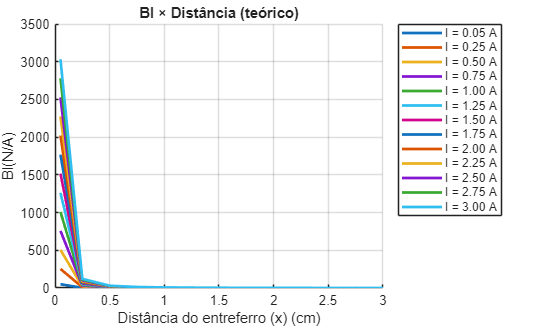


%% --- 6. Plotting the Magnetic Force (Fm) vs. Distance ---

figure;
hold on;
grid on;

% Plot Fm vs. Distance for each current
for j = 1:length(I_A)
    plot(x_cm, Bl_matrix(:, j), 'LineWidth', 2);
end

% --- Labels and Title for the plot ---
xlabel('Distância do entreferro (x) (cm)');
ylabel('Bl(N/A)');
title('Bl × Distância (teórico)');

% Generate legend labels
legend_labels = arrayfun(@(i) sprintf('I = %.2f A', i), I_A, 'UniformOutput', false);
legend(legend_labels, 'Location', 'bestoutside');
hold off;